# H4

Es vol tenir una útil aplicació de visió per computador que compti pedretes en la sorra. Amb aquest objectiu caldrà crear una aplicació que compti el numero de pedretes que hi en la imatge i que tinguin unes mides entre un cert màxim i mínim a determinar per l’usuari. La definició de mida d’una pedreta és lliure i caldrà que la definiu vosaltres mateixos. Mostreu el resultat fent una superposició de les pedretes segmentades sobre la imatge original.

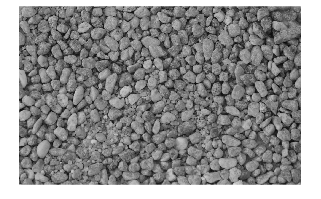

I = rgb2gray(imread('pedres.jpg'));
imshow(I);

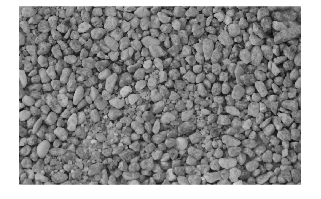


% filtrar
SE = ones(3,3);
IF = imclose(I,SE);
IF = imopen(IF,SE);
imshow(IF);

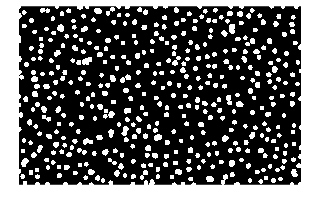


% maxims regionals
SE = fspecial("disk",10) > 0; % ajustat 20 la mida del que estem buscant
IO = imopen(I,SE);
MR = imregionalmax(IO);
imshow(MR);

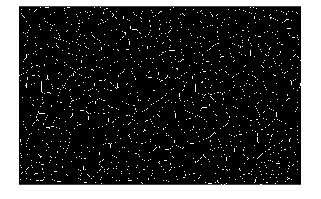


% SKIZ
SK = bwskel(not(MR)); 
SKIZ = bwmorph(SK,'spur',Inf); 
SKIZP = SKIZ & not(bwhitmiss(SKIZ, [-1 -1 -1; -1 1 -1; -1 -1 -1]));
imshow(SKIZP,[]);

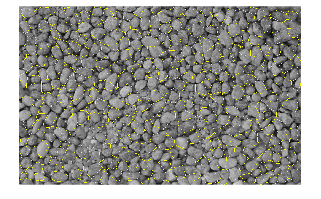

RGB = imoverlay(I,SKIZP);
imshow(RGB);

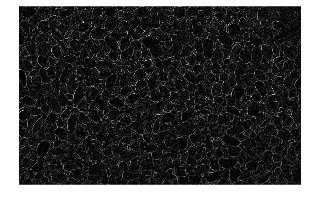


% imatge gradient
G = imgradient(IF);
imshow(G,[]);

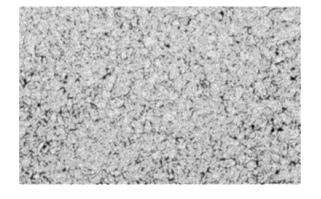


% watershed
TD = -bwdist(not(G),"quasi-euclidean");
TD = medfilt2(TD,[10 10]);
imshow(TD,[]);

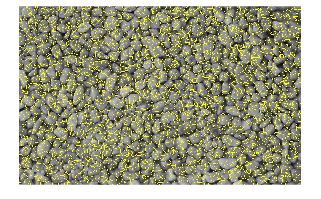

TD(not(I)) = -Inf;

WS = watershed(TD);
IB = WS == 0;
RGB = imoverlay(I,IB);
imshow(RGB);